clc;
clear all;
close all;

## Graphic

g = ncgr_graphic();

global N_DOFS;
N_DOFS = 3;

## 3-R-planar robot DH-Parameters

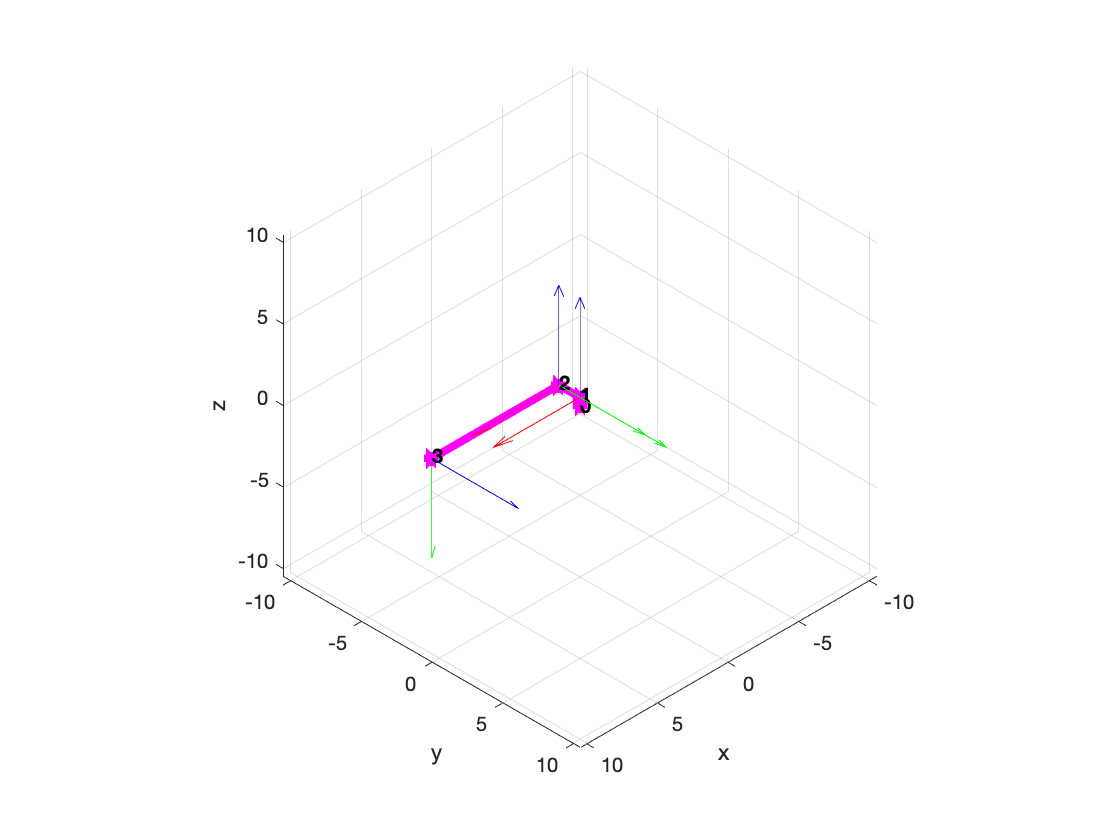

theta = [0 -pi/2 -pi/2];
alpha = [0 0 -pi/2];
offset = [0 0 0];
d = [0 1.5 0];
a = [0 1.5 9];
type = ['r','r','r'];
base = [0; 0; 0];

planar_3r = cgr_create(theta, d, a, alpha, offset, type, base, ...
    [pi/2; pi/2; pi/2], [-pi/2; -pi/2; -pi/2]);  % joint limts!
planar_3r = cgr_self_update(planar_3r, [0; 0; 0], base);
g = ncgr_plot(g, planar_3r, [1 1 1], 1);

## Demo for inverse kinematics

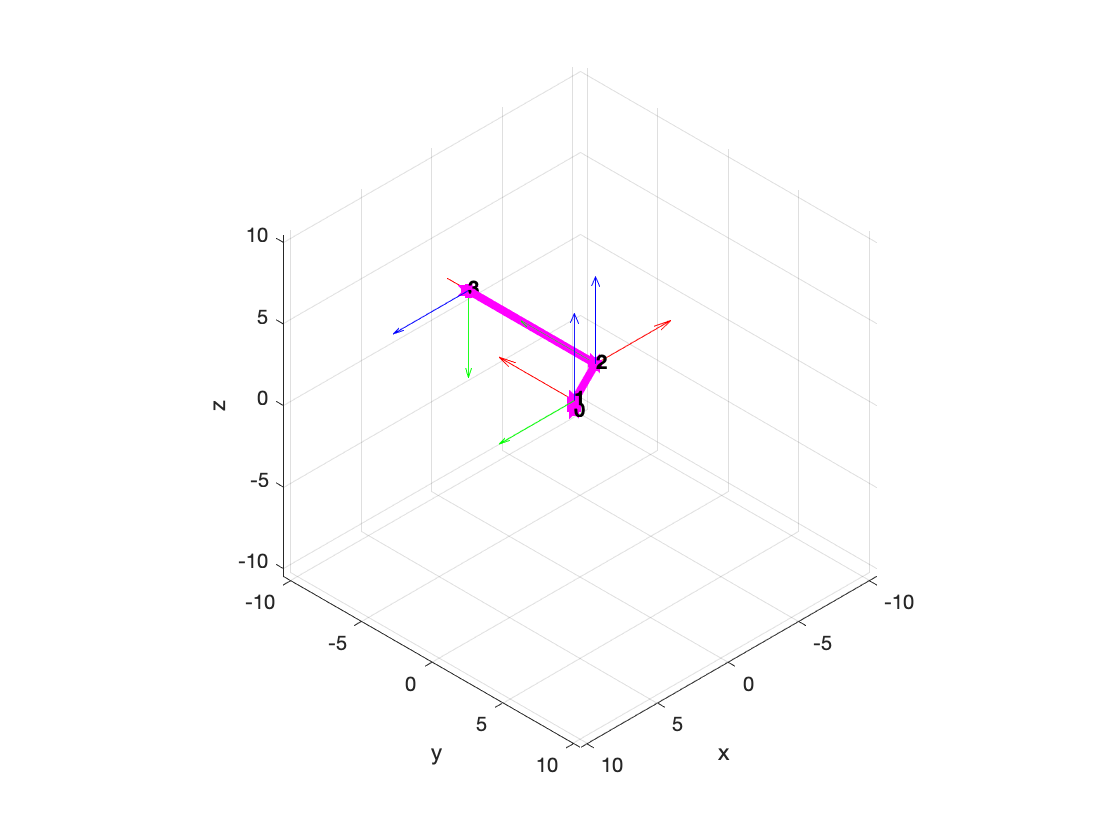

for ii = 0: 0.1: 0.4
    base(1) = ii;
    for x = 0.5+ii :0.1: 1+ii
        [q, k, err]= cgr_ikine1(planar_3r, [x; 0; 0], 0.01, 100);
        %[q, k, err]= cgr_ikine2(planar_4r, [x; 0; 0], 2, 0.01, 100);
        planar_3r = cgr_self_update(planar_3r, q, base);
        g = ncgr_plot(g, planar_3r);
        pause(0.1);
    end
end

## Demo for inverse kinematics

for ii = 0: 0.1: 0.4
    base(1) = ii;
    for x = 0.5+ii :0.1: 1.5+ii
        %[q, k, err]= cgr_ikine1(planar_4r, [x; 0; 0], 0.01, 100);
        [q, k, err]= cgr_ikine2(planar_3r, [x; 0; 0], 2, 0.01, 100);
        planar_3r = cgr_self_update(planar_3r, q, base);
        g = ncgr_plot(g, planar_3r);
        pause(0.1);
    end
end